# Lab5

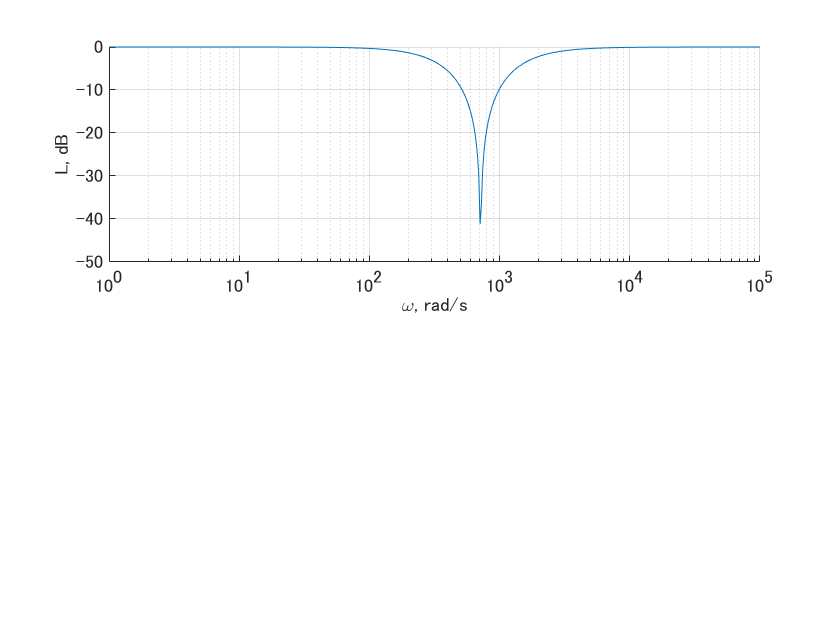

modelName = 'lab5s.slx'; %
VarName = 'var_94.mat'; %
load(VarName)

h = figure;
set(h,'DefaultAxesFontName','Times');

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')

Phase frequensy response

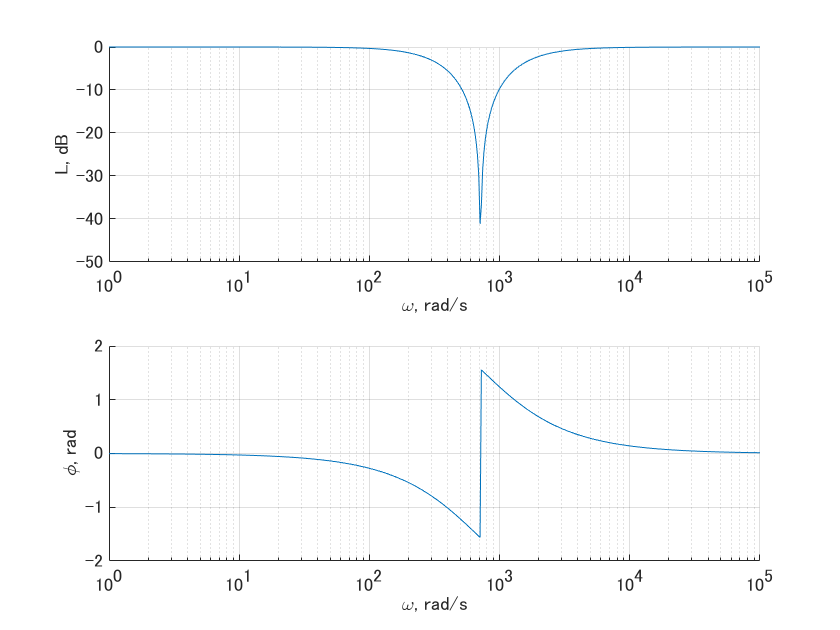

ax(2) = subplot(2,1,2);
    hold on
    grid on
    plot(w,phi)
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x') 

2.

 syms ur ul uc ir il ic
 syms dil duc
 syms e
 syms R L C

 eq(1) = ur == R*ir;
 eq(2) = ul == L*dil;
 eq(3) = ic == C*duc;
 eq(4) = ir == il + ic;
 eq(5) = ul == uc;
 eq(6) = ur+uc == e; 

 S1 = solve(eq,[dil duc ur ul ir ic]);
 disp(collect(S1.dil,[il uc e]))

$$\frac{\mathrm{uc}}{L}$$

 disp(collect(S1.duc,[il uc e]))

$$\left(-\frac{1}{C}\right)\,\mathrm{il}+\left(-\frac{1}{C\,R}\right)\,\mathrm{uc}+\frac{1}{C\,R}\,e$$

 disp(collect(S1.ur,[il uc e]))

$$-\mathrm{uc}+e$$

 mod.A = [0 1/L;...
     -1/C -1/C/R];
 mod.B = [0;1/(C*R)];
 mod.C = [0 -1];
 mod.D = [1];

 syms s
 Wob = mod.C*(s*eye(2)-mod.A)^-1*mod.B+mod.D

$$Wob = 1-\frac{L\,s}{C\,L\,R\,s^{2}+L\,s+R}$$

 disp(collect(Wob,s))

$$\frac{\left(C\,L\,R\right)\,s^{2}+R}{\left(C\,L\,R\right)\,s^{2}+L\,s+R}$$

## 3.Estimating

load(VarName)
h = figure;
set(h,'DefaultAxesFontName','Times');

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')
ax(2) = subplot(2,1,2);
    hold on
    grid on
    plot(w,phi)
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x') 

 est.om1 = 707.95;  % 频率
 est.T = est.om1^-1;
 fprintf('w = %.1frad/s\n',est.om1)

w = 708.0rad/s


 fprintf('T = %.1fms\n',est.T*1000)

T = 1.4ms


## fInd parameter ksi

 syms T ksi om H2
 Wjw = (T^2*(1i*om)^2+1)/(T^2*(1i*om)^2+2*T*ksi*(1i*om)+1);
 eqn = H2 == (-T^2*(om)^2+1)^2/((2*T*ksi*(om))^2+(-T^2*(om)^2+1)^2);
 S2 = solve(eqn,[ksi]);
 disp(S2)

$$\left(\begin{array}{c} -\frac{\left(T\,\mathrm{om}-1\right)\,\left(T\,\mathrm{om}+1\right)\,\sqrt{-\frac{H_{2}-1}{H_{2}}}}{2\,T\,\mathrm{om}}\\ \frac{\left(T\,\mathrm{om}-1\right)\,\left(T\,\mathrm{om}+1\right)\,\sqrt{-\frac{H_{2}-1}{H_{2}}}}{2\,T\,\mathrm{om}} \end{array}\right)$$

 ind = 300;
 mes.w = w(ind);
 mes.Lw = Lw(ind);
 mes.H = 10^(mes.Lw/20);
 mes.H2 = mes.H^2;

 est.ksi = (est.T*mes.w-1)*(est.T*mes.w+1)*...
     sqrt(-(mes.H2-1)/mes.H2)/(2*est.T*mes.w)

est = 包含以下字段的 struct :
    om1: 707.9500
      T: 0.0014
    ksi: 1.0188
      s: [0.0000 + 1.0000i 0.0000 + 1.0233i 0.0000 + 1.0471i 0.0000 + 1.0715i 0.0000 + 1.0965i 0.0000 + 1.1220i 0.0000 + 1.1482i 0.0000 + 1.1749i 0.0000 + 1.2023i 0.0000 + 1.2303i 0.0000 + 1.2589i 0.0000 + 1.2882i 0.0000 + 1.3183i 0.0000 + 1.3490i … ]


##  Estimated frequency response

est.s = 1i*w;
Wf = (est.T^2*est.s.^2+1)./(est.T^2*est.s.^2+2*est.T*est.ksi*est.s+1);
Lf = 20*log10(abs(Wf));
psif = angle(Wf);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

Logarithm-amplitude frequency response

ax(1) = subplot(2,1,1);
    hold on
    grid on
    plot(w,Lw)
    plot(w,Lf) %add this line
    set(ax(1),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\itL\rm,\it dB')

Phase frequency response

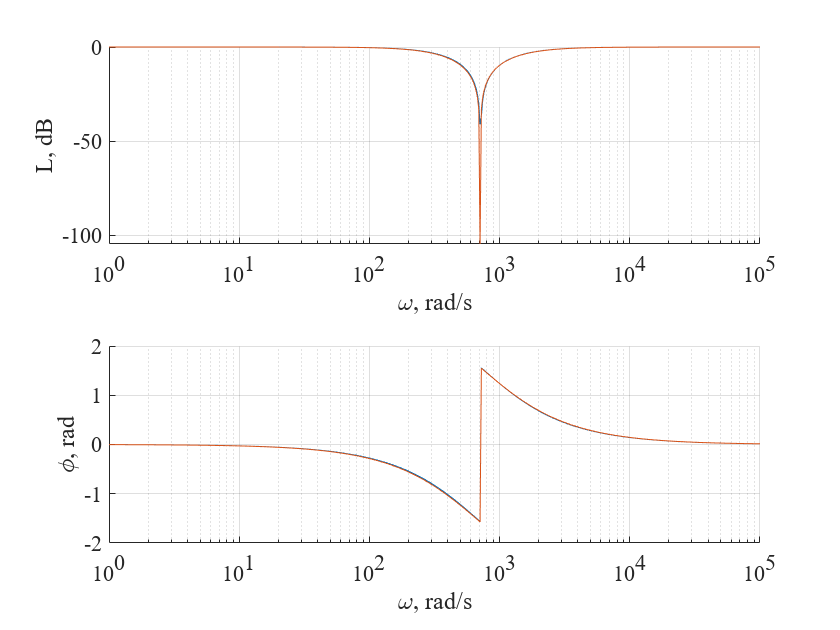

ax(2) = subplot(2,1,2);
    hold on
    grid on
    plot(w,phi)
    plot(w,psif) %add this line
    set(ax(2),'XScale','Log')
    xlabel('\omega,\it rad\rm/\its')
    ylabel('\phi\rm,\it rad')  

 linkaxes(ax,'x')

## 5.Checking

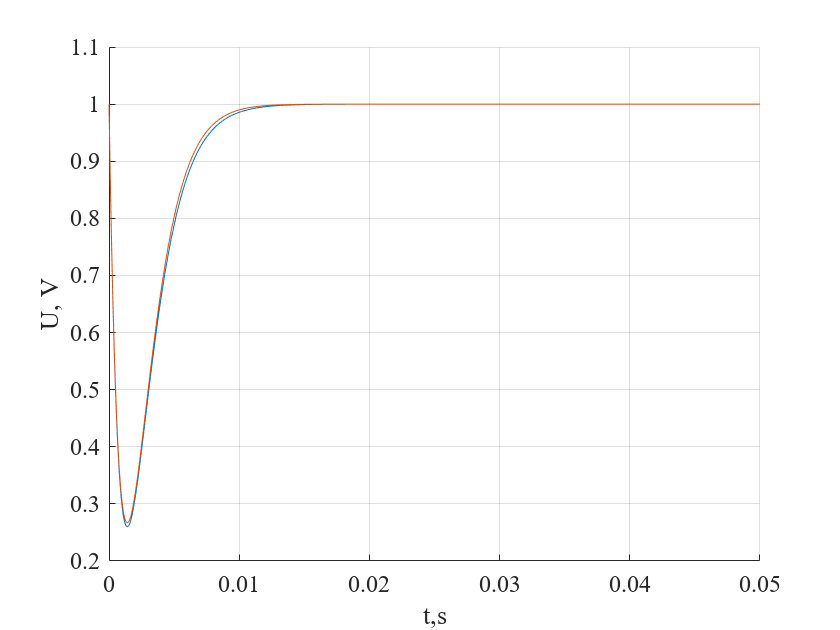

ob.C = 1e-3;
ob.L = est.T^2/ob.C;
ob.R = ob.L/(2*est.T*est.ksi);

Tmdl = 0.05;
Ts = 1e-4;

warning off
SimNew = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
warning on

tn = SimNew.tout(:,1);
im_y = SimNew.yout.get('u_R').Values.Data;
im_y = squeeze(im_y);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
    hold on
    grid on
    plot(tn, im_y)
    plot(t, y)

    xlabel('\itt\rm,\its')
    ylabel('\itU\rm,\it V')

    er = std(im_y-y)

er = 0.0040